# Controlled bond expansion (CBE) DMRG for ground state search

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

Here we will implement the controlled bond expansion (CBE) scheme that can improve DMRG or TDVP type of methods. With CBE, one can systematically identifiy the relevant subspace of the discarded bond space and append the subspace to the kept bond space, expanding the bond space in a controlled way; hence the name. Since wider bond spaces can be explored efficiently, the one-site updates (DMRG or TDVP type) complemented with CBE may overcome typical weakness of the one-site methods, such as inability to adjust bond dimensions and vulnerability to local minima. Therefore, one can achieve the accuracy and convergence comparable to those of the two-site update, with computational cost comparable with that of the one-site update.

The applications of CBE to DMRG ground-state search and TDVP are demonstrated in Gleis2022a [[A. Gleis, J.-W. Li, and J. von Delft, arXiv:2207.14712 (2022)](https://arxiv.org/abs/2207.14712)] and Li2022 [[J.-W. Li, A. Gleis, and J. von Delft, arXiv:2208.10972 (2022)](https://arxiv.org/abs/2208.10972)], respectively. These papers demonstrate that the CBE becomes advantageous, especially for the systems with large local space dimensions. The CBE scheme is formulated in terms of the kept and discarded projectors, introduced in Gleis2022 [[A. Gleis, J.-W. Li, and J. von Delft, arXiv:2207.13161 (2022)](https://arxiv.org/abs/2207.13161)]. For details of the CBE algorithm, please refer to the section "Controlled bond expansion" and Fig. 2 of Gleis2022a.

## Exercise (a): Complete the function for CBE-DMRG

There is a function `DMRG_GS_CBE_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

To demonstrate the strength of CBE-DMRG, we consider free spinful fermions on a tight-binding chain,


$$\hat{H} = -t \sum_{i = 1}^{L-1} \sum_{\sigma = {\uparrow},{\downarrow}} ( \hat{c}_{i+1,\sigma}^\dagger \hat{c}_{i,\sigma} + \hat{c}_{i,\sigma}^\dagger \hat{c}_{i+1,\sigma} ) ,$$


where $\hat{c}_{i\sigma}^\dagger$ creates a particle of spin-$\sigma$ at site $i$. Here we choose the chain length $L = 30$ and the hopping amplitude $t = 1$. We chose this fermionic model instead of the XY spin-1/2 chain (that has been considered as a demonstration example very often), since the computational advantage of CBE is better visible for the systems with larger local space dimensions. For this model the dimensions are 4, while for the spin-1/2 model they are 2.

clear

% system parameters
t = 1; % hopping amplitude
L = 30; % number of sites in a chain

Since the Hamiltonian is quadratic, we can obtain the exact value of the ground-state energy, by solving the single-particle Hamiltonian.

E0_exact = nonIntTB(ones(L-1,1)*t)*2;

Note that we multiplied 2, since the states of spin-up and down particles independently contribute to the ground-state energy (i.e., sum over two spin species).

% Local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(6,6);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = Z*F(:,:,1);
Hloc{3,1} = Z*F(:,:,2);
Hloc{4,1} = Hloc{2,1}';
Hloc{5,1} = Hloc{3,1}';
Hloc{6,2} = -t*F(:,:,1)';
Hloc{6,3} = -t*F(:,:,2)';
Hloc{6,4} = -t*F(:,:,1);
Hloc{6,5} = -t*F(:,:,2);
Hloc{6,6} = I;

Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

We consider two examples with different choices of the initial MPSs. As the first example, we initialize the MPS as a separable state. Its tensors can be chosen randomly, but here we set them deterministically, so that readers can try to reproduce the numbers here.

Nkeep = 100;
Nsweep = 7;
delta = 0.1;

Minit = cell(1,L);

for itN = (1:L)
    Minit{itN} = reshape([cos(2*pi*itN/L);sin(2*pi*itN/L)]* ...
        [cos(2*pi*itN/L),sin(2*pi*itN/L)],[1 1 size(I,2)]);
end

[M_CBE,E0_CBE,Eiter_CBE] = DMRG_GS_CBE_Ex (Minit,Hs,Nkeep,Nsweep,delta);

22-11-08 13:18:34 | CBE-DMRG: ground state search
22-11-08 13:18:34 | # of sites = 30, Nkeep = 100, # of sweeps = 7 x 2
22-11-08 13:18:34 | Sweep #1/14 (right -> left) : Energy = -29.71297
22-11-08 13:18:34 | Sweep #2/14 (left -> right) : Energy = -36.61177
22-11-08 13:18:35 | Sweep #3/14 (right -> left) : Energy = -37.2838
22-11-08 13:18:35 | Sweep #4/14 (left -> right) : Energy = -37.4135
22-11-08 13:18:36 | Sweep #5/14 (right -> left) : Energy = -37.45362
22-11-08 13:18:36 | Sweep #6/14 (left -> right) : Energy = -37.47357
22-11-08 13:18:37 | Sweep #7/14 (right -> left) : Energy = -37.4826
22-11-08 13:18:38 | Sweep #8/14 (left -> right) : Energy = -37.48538
22-11-08 13:18:40 | Sweep #9/14 (right -> left) : Energy = -37.48654
22-11-08 13:18:41 | Sweep #10/14 (left -> right) : Energy = -37.48677
22-11-08 13:18:43 | Sweep #11/14 (right -> left) : Energy = -37.48688
22-11-08 13:18:45 | Sweep #12/14 (left -> right) : Energy = -37.4869
22-11-08 13:18:47 | Sweep #13/14 (right -> left) : En

disptime(['CBE-DMRG error = ',sprintf('%.5g',E0_CBE-E0_exact)]);

22-11-08 13:18:49 | CBE-DMRG error = 0.00041798


disp(M_CBE); % tensor sizes

  Columns 1 through 8

    {1×4×4 double}    {4×16×4 double}    {16×64×4 double}    {64×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}

  Columns 9 through 15

    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}

  Columns 16 through 22

    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}

  Columns 23 through 30

    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×100×4 double}    {100×64×4 double}    {64×16×4 double}    {16×4×4 double}    {4×1×4 double}



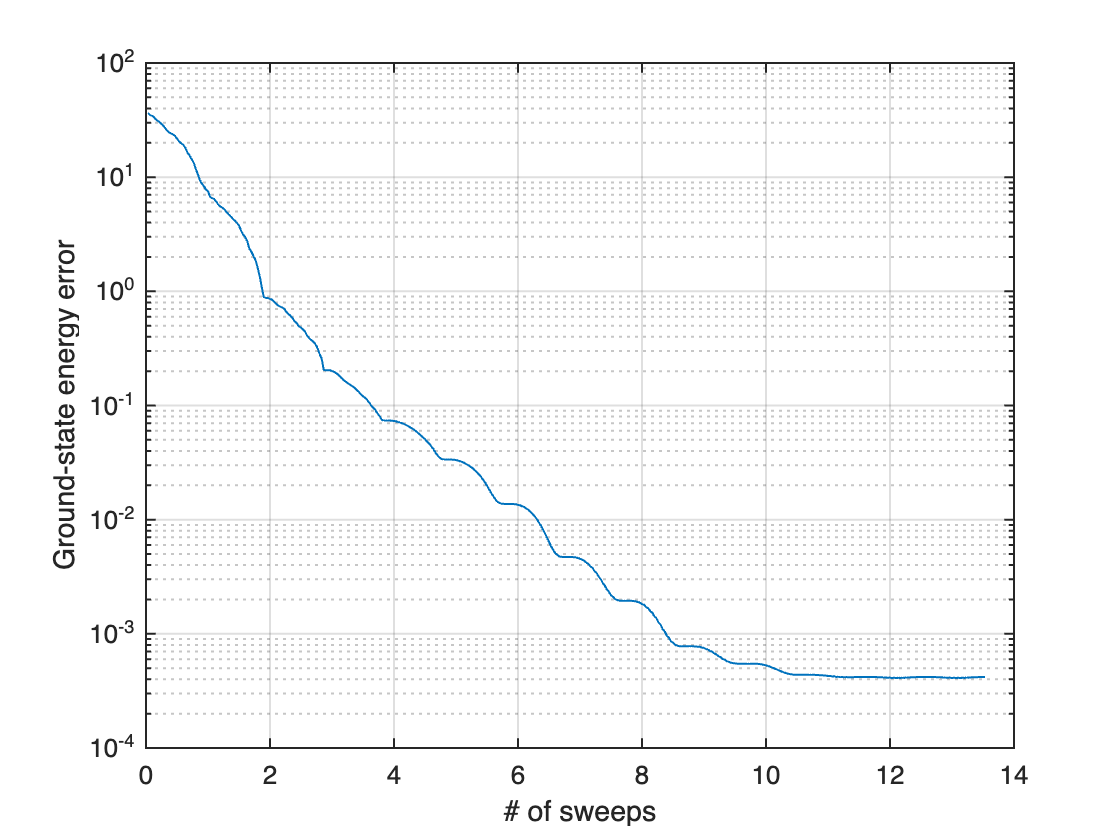


figure;
plot((1:numel(Eiter_CBE))/L,Eiter_CBE(:)-E0_exact,'LineWidth',1);
set(gca,'XScale','Linear','YScale','log','FontSize',13,'LineWidth',1);
xlim([0 2*Nsweep]);
grid on;
xlabel('# of sweeps');
ylabel('Ground-state energy error');

This example shows that the CBE-DMRG can expand bond dimensions on the fly, while the standard 1-site DMRG cannot.

As the second case, we consider the result of the iterative diagonalization. With this, we compare the CBE-DMRG and the 2-site DMRG. Here we choose smaller `Nsweep` since the variational optimization starts from a better initial guess.

Nsweep = 3;

Minit = cell(1,L);

% tensors for the vaccum (i.e., dummy leg)
Hprev = 1; % initialize Hamiltonian with 1, as we will use MPO
Aprev = 1; % identity tensor for the dummy leg

for itN = (1:L)
    % add new site
    Anow = getIdentity(Aprev,2,I,2,[1 3 2]);
    Hnow = updateLeft(Hprev,3,Anow,Hs{itN},4,Anow);

    Hmat = Hnow(:,:,1);
    [V,D] = eig((Hmat+Hmat')/2);
    [D,ids] = sort(diag(D),'ascend');
    if itN < L
        Ntr = min([numel(D);Nkeep]);
    else
        Ntr = 1;
    end
    V = V(:,ids(1:Ntr));
    
    Anow = contract(Anow,3,2,V,2,1,[1 3 2]);

    Minit{itN} = Anow;
    
    Hprev = contract(Hnow,3,2,V,2,1);
    Hprev = contract(V',2,2,Hprev,3,1,[1 3 2]);
    Aprev = Anow;
end

[~,E0_CBE,Eiter_CBE] = DMRG_GS_CBE_Ex (Minit,Hs,Nkeep,Nsweep,delta);

22-11-08 13:18:51 | CBE-DMRG: ground state search
22-11-08 13:18:51 | # of sites = 30, Nkeep = 100, # of sweeps = 3 x 2
22-11-08 13:18:53 | Sweep #1/6 (right -> left) : Energy = -37.48566
22-11-08 13:18:55 | Sweep #2/6 (left -> right) : Energy = -37.48677
22-11-08 13:18:57 | Sweep #3/6 (right -> left) : Energy = -37.4869
22-11-08 13:18:59 | Sweep #4/6 (left -> right) : Energy = -37.4869
22-11-08 13:19:01 | Sweep #5/6 (right -> left) : Energy = -37.4869
22-11-08 13:19:03 | Sweep #6/6 (left -> right) : Energy = -37.4869
Elapsed time: 12.66s, CPU time: 97.53s, Avg # of cores: 7.703


disptime(['CBE-DMRG error = ',sprintf('%.5g',E0_CBE-E0_exact)]);

22-11-08 13:19:03 | CBE-DMRG error = 0.00041728


[~,E0_2site,Eiter_2site] = DMRG_GS_2site (Minit,Hs,Nkeep,Nsweep);

22-11-08 13:19:03 | Two-site DMRG: ground state search
22-11-08 13:19:03 | # of sites = 30, Nkeep = 100, # of sweeps = 3 x 2
22-11-08 13:19:07 | Sweep #1/6 (right -> left) : Energy = -37.48669
22-11-08 13:19:12 | Sweep #2/6 (left -> right) : Energy = -37.48689
22-11-08 13:19:16 | Sweep #3/6 (right -> left) : Energy = -37.4869
22-11-08 13:19:21 | Sweep #4/6 (left -> right) : Energy = -37.4869
22-11-08 13:19:25 | Sweep #5/6 (right -> left) : Energy = -37.4869
22-11-08 13:19:30 | Sweep #6/6 (left -> right) : Energy = -37.4869
Elapsed time: 26.47s, CPU time: 139.4s, Avg # of cores: 5.268


disptime(['2-site DMRG error = ',sprintf('%.5g',E0_2site-E0_exact)]);

22-11-08 13:19:30 | 2-site DMRG error = 0.00042332


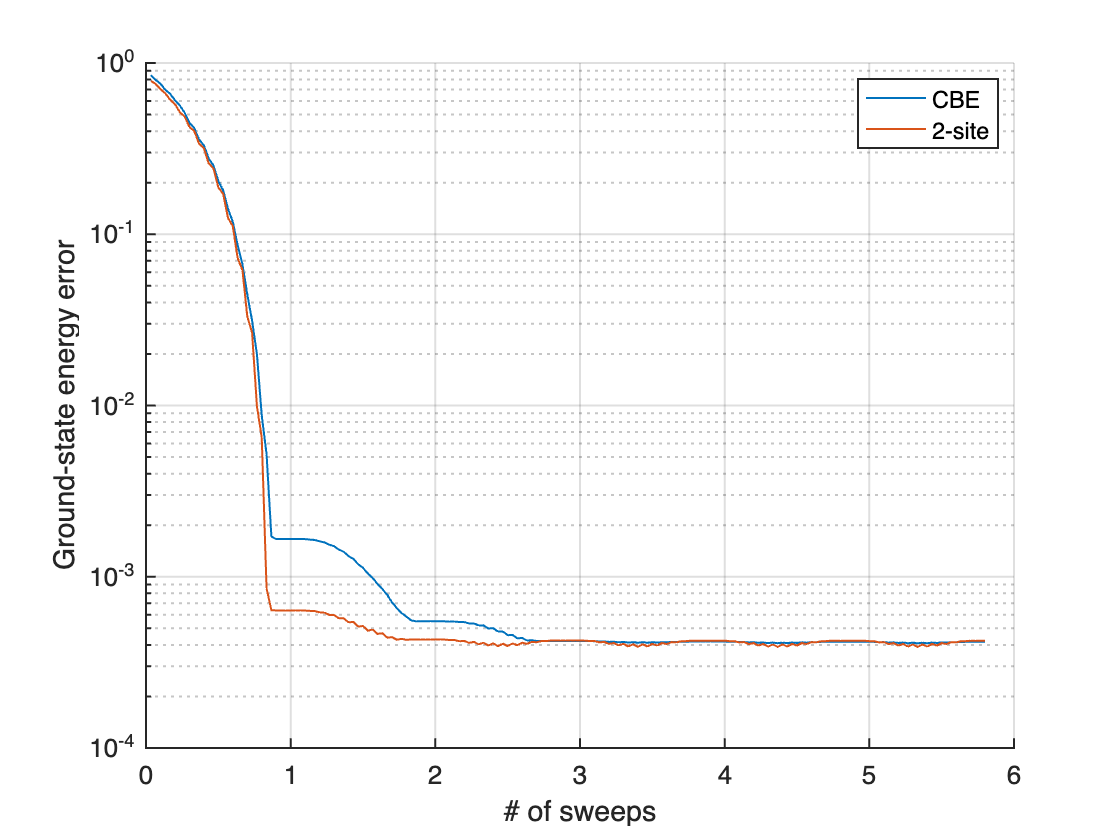


figure;
hold on;
plot((1:numel(Eiter_CBE))/L,Eiter_CBE(:)-E0_exact,'LineWidth',1);
plot((1:numel(Eiter_2site))/L,Eiter_2site(:)-E0_exact,'LineWidth',1);
hold off;
set(gca,'XScale','Linear','YScale','log','FontSize',13,'LineWidth',1);
xlim([0 2*Nsweep]);
grid on;
xlabel('# of sweeps');
ylabel('Ground-state energy error');
legend({'CBE','2-site'})

We see that the CBE-DMRG and the 2-site DMRG lead to comparable convergence, while the CBE-DMRG is faster in terms of wall and CPU times.

## Exercise (b): Error analysis

With CBE, now we can measure the discarded weights as the fifth output of `DMRG_GS_CBE_Ex.m`. (See also the documentation on the output `dw` in the function.) Repeat the CBE-DMRG calculation of the ground state of the free spinful fermion model for different values of `Nkeep`, and measure the discarded weight and the two-site variance $\Delta_E^{2s}$ (the latter via `DMRG/varE_2site.m`). Show how the ground-state energy error scales with the discarded weight and the two-site variance.